# Códigos de Proyecto

Sección: 7

N° de grupo: 4

Título del Proyecto: Modelación numérica de la distribución térmica en una placa electrónica idealizada mediante Diferencias Finitas, Gauss-Seidel y Gradiente Conjugado

Integrantes:

1. Leon Vasquez, Jose Roberto — 100%

2. Contreras Sosa, Hector Fabian — 100%

3. Rosales Esteban, Antony Yonel (líder) — 100%

4. Oceda Chavez, Elizabeth Emperatriz — 100%

5. Roman Ramirez, Andre Moises — 100%

## Configuración del modelo y reproducibilidad

Se establecen los parámetros geométricos, térmicos y numéricos del caso base, y se prepara una carpeta nueva para mantener aislados los resultados de cada corrida. El bloque configura la malla de referencia y las opciones compartidas por los métodos.

clearvars; close all; clc;

archivoLive = matlab.desktop.editor.getActiveFilename();
if isempty(archivoLive)
    % Esta alternativa solo se usa en ejecuciones programáticas; Run All toma la ruta del documento activo.
    archivoLive = getappdata(0, 'MN_Grupo4_liveScriptPath');
end
assert(~isempty(archivoLive) && isfile(archivoLive), ...
    'Ejecute el Live Script desde Live Editor o proporcione su ruta al ejecutor.');
carpetaLive = fileparts(archivoLive);
identificadorCorrida = ['run_' char(datetime('now','Format','yyyyMMdd_HHmmss')) '_' char(java.util.UUID.randomUUID)];
carpetaCorrida = fullfile(carpetaLive, 'resultados', identificadorCorrida);
assert(~isfolder(carpetaCorrida), 'El identificador de corrida ya existe.');
mkdir(carpetaCorrida);

cfg = planteamiento_modelo();
modelo = discretizacion_matriz(cfg, cfg.baselineGrid(1), cfg.baselineGrid(2));
x0 = cfg.initialTemperature * ones(modelo.nUnknowns, 1);
opciones = struct('tolerance', cfg.tolerance, 'maxIterations', cfg.maxIterations, ...
    'checkpointFractions', cfg.checkpointFractions);

## Formulación y discretización por diferencias finitas

Modelo térmico. Se representa la conducción estacionaria bidimensional en una placa homogénea e isotrópica, con fuentes rectangulares de CPU y GPU y temperatura de contorno Dirichlet de 25 °C. El dominio de 0.24 m × 0.16 m ocupa 0.0384 m².

Discretización por diferencias finitas. La función de discretización aplica el esquema de diferencias finitas centrales sobre la malla y produce el sistema algebraico correspondiente a las incógnitas interiores. El tamaño de la malla fija las dimensiones del sistema disperso.

Ensamblaje de la matriz dispersa. El ensamblaje incorpora las fuentes mediante solapes de volúmenes duales para conservar su potencia. Se comprueban las dimensiones, el número de incógnitas y la simetría de la matriz.

fprintf('Malla base: %d × %d nodos; %d incógnitas interiores.\n', ...
    modelo.nx, modelo.ny, modelo.nUnknowns);

Malla base: 49 × 33 nodos; 1457 incógnitas interiores.


fprintf('Potencia integrada: CPU %.12g W; GPU %.12g W.\n', ...
    modelo.sourcePower.cpu, modelo.sourcePower.gpu);

Potencia integrada: CPU 12 W; GPU 18 W.


assert(modelo.nUnknowns == (modelo.nx-2)*(modelo.ny-2));
assert(modelo.symmetryError < 1e-14);

## Experimento A: caso base, métodos y convergencia

El caso base utiliza la malla de referencia, CPU de 12 W, GPU de 18 W y contorno a 25 °C. Se contrastan los dos métodos iterativos con una referencia directa sobre el mismo sistema discreto.

Solución directa de referencia. La solución dispersa directa sirve como referencia algebraica del sistema discretizado; no representa por sí sola el error espacial respecto a la solución continua.

Gauss-Seidel. Gauss-Seidel actualiza secuencialmente las incógnitas del sistema disperso y registra su convergencia. Se emplean el vector inicial común y la tolerancia relativa definida en la configuración.

Gradiente Conjugado. El Gradiente Conjugado se aplica a la matriz simétrica definida positiva del modelo. Usa el mismo vector inicial y criterio de parada para permitir la comparación de iteraciones y residuos.

tiempoDirecto = tic;
solucionDirecta = modelo.A \ modelo.b;
tiempoDirecto_s = toc(tiempoDirecto);
gaussSeidel = metodo_gauss_seidel(modelo.A, modelo.b, x0, opciones);
gradienteConjugado = metodo_gradiente_conjugado(modelo.A, modelo.b, x0, opciones);
comparacionBase = comparacion_metodos(modelo, solucionDirecta, gaussSeidel, gradienteConjugado);
metricasDirectas = metricas_temperatura(modelo, solucionDirecta);
campoBase = campo_temperatura(modelo, solucionDirecta);
assert(strcmp(gaussSeidel.status,'converged') && strcmp(gradienteConjugado.status,'converged'));

fprintf('Temperatura máxima de referencia: %.9f °C; residuo directo: %.3e.\n', ...
    metricasDirectas.Tmax_C, metricasDirectas.relative_residual);

Temperatura máxima de referencia: 77.759239210 °C; residuo directo: 3.687e-15.


traducirMetodo = @(valor) replace(replace(string(valor),"Sparse direct","Referencia directa"), ...
    "Conjugate Gradient","Gradiente conjugado");
tablaComparacionVista = comparacionBase;
tablaComparacionVista.metodo = traducirMetodo(tablaComparacionVista.metodo);
tablaComparacionVista.Properties.VariableNames = ...
    {'Metodo','Iteraciones','ResiduoRelativo','TemperaturaMaxima_C', ...
    'ErrorAlgebraicoMaximo_C','ErrorIterativoRelativo_GS'};
tablaComparacionVista.ResiduoRelativo = compose('%.3e',tablaComparacionVista.ResiduoRelativo);
tablaComparacionVista.ErrorAlgebraicoMaximo_C = ...
    compose('%.3e',tablaComparacionVista.ErrorAlgebraicoMaximo_C);
disp(tablaComparacionVista);

           Metodo            Iteraciones    ResiduoRelativo    TemperaturaMaxima_C    ErrorAlgebraicoMaximo_C    ErrorIterativoRelativo_GS
    _____________________    ___________    _______________    ___________________    _______________________    _________________________

    "Referencia directa"           0         {'3.687e-15'}           77.759                {'0.000e+00'}         "No aplica (referencia)" 
    "Gauss-Seidel"              2145         {'9.942e-09'}           77.759                {'1.167e-05'}         "1.050e-09"              
    "Gradiente conjugado"        127         {'9.284e-09'}           77.759                {'4.928e-07'}         "No aplica"              



## Experimento B: refinamiento espacial

Se resuelve el modelo en las cuatro mallas 25 × 17, 49 × 33, 97 × 65 y 193 × 129 nodos. Se comparan temperaturas, iteraciones y tiempos; las diferencias entre campos consecutivos se calculan mediante interpolación bilineal y representan cambio espacial, no error exacto.

## Experimento C: sensibilidad a las potencias

Las potencias de CPU y GPU se varían de forma independiente según los escenarios configurados. Se registran la temperatura máxima y su ubicación para separar la sensibilidad a cada fuente, y se generan las tablas y curvas asociadas a esas variaciones.

## Experimento D: validación y estrés numérico

Se revisan simetría y definitud positiva, conservación de potencia, linealidad y tolerancias. También se ejecutan pruebas de estrés y un caso deliberado de no convergencia para verificar que el estado de parada se informe explícitamente; las potencias extremas son pruebas numéricas.

## Ejecución y exportación de los experimentos A–D

La función de experimentos ejecuta los escenarios A–D y escribe sus tablas CSV, estados MAT, metadatos JSON, figuras y reporte de validación en la carpeta exclusiva de esta corrida. Los tiempos se vuelven a medir en el entorno actual y no sustituyen las mediciones históricas.

opcionesTiempo = struct('warmupRuns',1,'measuredRuns',3);
tiempoExperimentos = tic;
resultados = experimentos(fullfile(carpetaCorrida,'resultados'), opcionesTiempo);
tiempoExperimentos_s = toc(tiempoExperimentos);
validacion = validar_simulacion();
assert(validacion.passed, 'Falló una o más verificaciones del sistema.');

## Tablas y resultados de los experimentos

Se cargan los CSV de la corrida recién generada y se presentan los resúmenes de métodos iterativos, refinamiento, sensibilidad y estrés. Se muestran vistas concisas con magnitudes y unidades; los CSV conservan todas las columnas y filas.

resumenSolvers = readtable(fullfile(carpetaCorrida,'resultados','escenario_base','solver_summary.csv'));
tablaRefinamiento = resultados.refinement;
tablaSensibilidad = resultados.sensitivity;
tablaEstres = resultados.stress;
resumenSolversVista = resumenSolvers(:, ...
    {'solver','tolerance','iter','rel_residual','Tmax_C','time_median_s'});
resumenSolversVista.solver = traducirMetodo(resumenSolversVista.solver);
resumenSolversVista.Properties.VariableNames = ...
    {'Metodo','Tol','Iter','ResiduoRel','Tmax_C','Tiempo_s'};

tablaRefinamientoTermicaVista = tablaRefinamiento(:, ...
    {'unknowns','Tmax_C','spatial_max_abs_difference_C','algebraic_max_abs_error_C'});
tablaRefinamientoTermicaVista = addvars(tablaRefinamientoTermicaVista, ...
    string(compose('%d x %d',tablaRefinamiento.nx,tablaRefinamiento.ny)), ...
    'Before','unknowns','NewVariableNames','mesh');
tablaRefinamientoTermicaVista.Properties.VariableNames = ...
    {'Malla','Incognitas','Tmax_C','DifEspacial_C','ErrorAlgebraico_C'};

tablaRefinamientoCostoVista = tablaRefinamiento(:, ...
    {'solver','nx','ny','unknowns','iter','time_median_s'});
tablaRefinamientoCostoVista.solver = traducirMetodo(tablaRefinamientoCostoVista.solver);
tablaRefinamientoCostoVista.Properties.VariableNames = ...
    {'Metodo','Nodos_x','Nodos_y','Incognitas','Iteraciones','TiempoMediano_s'};

tablaSensibilidadVista = tablaSensibilidad(:, ...
    {'varied_source','scale','cpu_power_W','gpu_power_W','Tmax_C','hotspot_x_m','hotspot_y_m'});
tablaSensibilidadVista.varied_source = upper(string(tablaSensibilidadVista.varied_source));
tablaSensibilidadVista.Properties.VariableNames = ...
    {'Fuente','Escala','CPU_W','GPU_W','Tmax_C','x_m','y_m'};

tablaEstresPruebasVista = tablaEstres(:, ...
    {'case','tol','solver','status','iterations','residual'});
tablaEstresPruebasVista.case = string(tablaEstresPruebasVista.case);
tablaEstresPruebasVista.case = replace(tablaEstresPruebasVista.case,'baseline_tolerance','Base');
tablaEstresPruebasVista.case = replace(tablaEstresPruebasVista.case,'extreme_positive_1000x','Potencia_1000x');
tablaEstresPruebasVista.case = replace(tablaEstresPruebasVista.case,'nonphysical_negative_cpu','CPU_negativa');
tablaEstresPruebasVista.solver = traducirMetodo(tablaEstresPruebasVista.solver);
casosVista = tablaEstresPruebasVista.case;
tablaEstresPruebasVista.Properties.VariableNames = ...
    {'Caso','Tol.','Metodo','Estado','Iter.','Residuo'};

tablaEstresTiemposVista = tablaEstres(:, ...
    {'case','solver','time_median_s','time_std_s'});
tablaEstresTiemposVista.case = casosVista;
tablaEstresTiemposVista.solver = traducirMetodo(tablaEstresTiemposVista.solver);
tablaEstresTiemposVista.Properties.VariableNames = ...
    {'Caso','Metodo','Mediana_s','DesvEst_s'};

disp(resumenSolversVista);

           Metodo             Tol     Iter    ResiduoRel    Tmax_C    Tiempo_s 
    _____________________    _____    ____    __________    ______    _________

    "Referencia directa"     1e-08       1    3.6867e-15    77.759    0.0017858
    "Gauss-Seidel"           1e-08    2145     9.942e-09    77.759      0.13997
    "Gradiente conjugado"    1e-08     127    9.2837e-09    77.759    0.0036636



disp(tablaRefinamientoTermicaVista);

       Malla       Incognitas    Tmax_C    DifEspacial_C    ErrorAlgebraico_C
    ___________    __________    ______    _____________    _________________

    "25 x 17"          345       77.409       0.23847          4.2227e-06    
    "25 x 17"          345       77.409       0.23847          2.7063e-07    
    "49 x 33"         1457       77.759      0.061593          1.1672e-05    
    "49 x 33"         1457       77.759      0.061593          4.9282e-07    
    "97 x 65"         5985       78.013      0.015536           3.296e-05    
    "97 x 65"         5985       78.013      0.015536          1.0237e-06    
    "193 x 129"      24257       78.034           NaN          9.2984e-05    
    "193 x 129"      24257       78.034           NaN          2.7939e-06    



disp(tablaRefinamientoCostoVista);

           Metodo            Nodos_x    Nodos_y    Incognitas    Iteraciones    TiempoMediano_s
    _____________________    _______    _______    __________    ___________    _______________

    "Gauss-Seidel"              25         17          345            572           0.011506   
    "Gradiente conjugado"       25         17          345             64          0.0005323   
    "Gauss-Seidel"              49         33         1457           2145            0.12737   
    "Gradiente conjugado"       49         33         1457            127          0.0032164   
    "Gauss-Seidel"              97         65         5985           7983             2.0454   
    "Gradiente conjugado"       97         65         5985            250           0.027934   
    "Gauss-Seidel"         

disp(tablaSensibilidadVista);

    Fuente    Escala    CPU_W    GPU_W    Tmax_C     x_m     y_m
    ______    ______    _____    _____    ______    _____    ___

    "CPU"        0        0       18      75.027     0.18    0.1
    "GPU"        0       12        0      58.351     0.06    0.1
    "CPU"      0.5        6       18      76.337     0.18    0.1
    "GPU"      0.5       12        9      60.419    0.065    0.1
    "CPU"        1       12       18      77.759    0.175    0.1
    "GPU"        1       12       18      77.759    0.175    0.1
    "CPU"      1.5       18       18      79.236    0.065    0.1
    "GPU"      1.5       12       27      102.66    0.175    0.1



disp(tablaEstresPruebasVista);

          Caso          Tol.            Metodo              Estado       Iter.     Residuo  
    ________________    _____    _____________________    ___________    _____    __________

    "Base"              1e-06    "Gauss-Seidel"           "converged"    1484     9.9518e-07
    "Base"              1e-06    "Gradiente conjugado"    "converged"     106     9.6893e-07
    "Base"              1e-08    "Gauss-Seidel"           "converged"    2145      9.942e-09
    "Base"              1e-08    "Gradiente conjugado"    "converged"     127     9.2837e-09
    "Base"              1e-10    "Gauss-Seidel"           "converged"    2806     9.9321e-11
    "Base"              1e-10    "Gradiente conjugado"    "converged"     148     7.4252e-11
    "Base"              1e-12    "Gauss-Seidel"    

disp(tablaEstresTiemposVista);

          Caso                 Metodo            Mediana_s    DesvEst_s 
    ________________    _____________________    _________    __________

    "Base"              "Gauss-Seidel"              0.1364      0.011474
    "Base"              "Gradiente conjugado"    0.0028862    0.00086927
    "Base"              "Gauss-Seidel"             0.20574     0.0019685
    "Base"              "Gradiente conjugado"    0.0031846    0.00042048
    "Base"              "Gauss-Seidel"             0.52547       0.17814
    "Base"              "Gradiente conjugado"    0.0045014    0.00057185
    "Base"              "Gauss-Seidel"             0.50656      0.065618
    "Base"              "Gradiente conjugado"     0.013626      0.011485
    "Potencia_1000x"    "Gauss-Seidel"              0.2601      0.027931
    "Potencia_1000x"    "Gradiente conjugado"    0.0054811  

## Reconstrucción de estados y generación de figuras

Los campos representativos muestran la evolución espacial de ambos métodos iterativos en varias iteraciones. La rutina de graficación exporta las figuras de A–D a partir de los datos de esta corrida, con escalas, unidades, títulos y leyendas definidos por cada experimento.

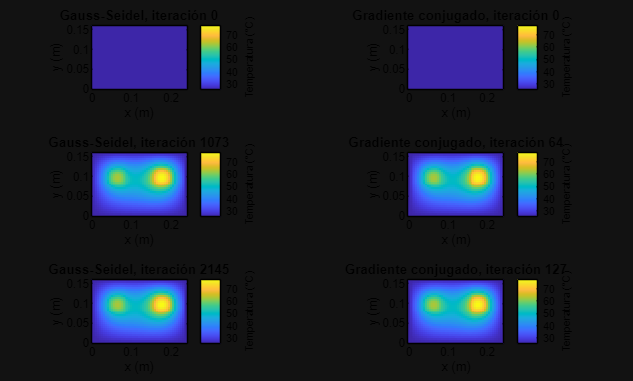

estadosRepresentativos = readtable(fullfile(carpetaCorrida,'resultados', ...
    'escenario_base','representative_states.csv'));
figuraEstados = figure('Name','A - Estados representativos','Color','w');
layoutEstados = tiledlayout(figuraEstados,3,2,'TileSpacing','loose','Padding','compact');
ordenSolvers = ["Gauss-Seidel"; "Conjugate Gradient"];
limitesTemperatura = [min(estadosRepresentativos.T_C), max(estadosRepresentativos.T_C)];
for indiceSolver = 1:numel(ordenSolvers)
    filasSolver = string(estadosRepresentativos.solver) == ordenSolvers(indiceSolver);
    iteracionesEstado = unique(estadosRepresentativos.iter(filasSolver),'stable');
    assert(numel(iteracionesEstado)==3, ...
        'Cada método debe incluir estados inicial, intermedio y final.');
    for indiceEstado = 1:numel(iteracionesEstado)
        seleccion = filasSolver & estadosRepresentativos.iter == iteracionesEstado(indiceEstado);
        xNodos = unique(estadosRepresentativos.x_m(seleccion));
        yNodos = unique(estadosRepresentativos.y_m(seleccion));
        temperaturaEstado = reshape(estadosRepresentativos.T_C(seleccion),numel(yNodos),numel(xNodos));
        indicePanel = (indiceEstado-1)*numel(ordenSolvers)+indiceSolver;
        ax = nexttile(layoutEstados,indicePanel);
        imagesc(ax,xNodos,yNodos,temperaturaEstado); axis(ax,'image','xy');
        clim(ax,limitesTemperatura);
        cb=colorbar(ax); cb.Label.String=['Temperatura (' char(176) 'C)'];
        set(ax,'Color','white','XColor','black','YColor','black','FontSize',7);
        ax.Title.Color='black'; ax.XLabel.Color='black'; ax.YLabel.Color='black';
        cb.Color='black'; cb.Label.Color='black';
        xlabel(ax,'x (m)'); ylabel(ax,'y (m)');
        nombreMetodo=replace(ordenSolvers(indiceSolver),"Conjugate Gradient","Gradiente conjugado");
        title(ax,sprintf('%s, iteración %d',nombreMetodo,iteracionesEstado(indiceEstado)), ...
            'FontSize',8);
    end
end

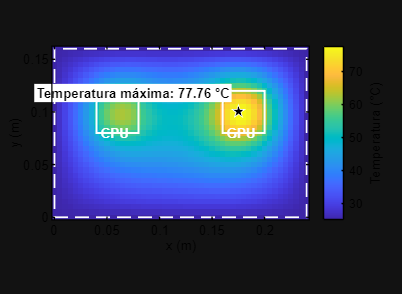

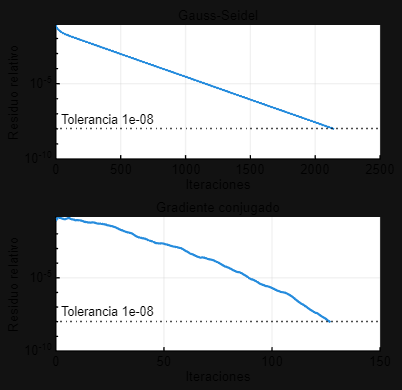

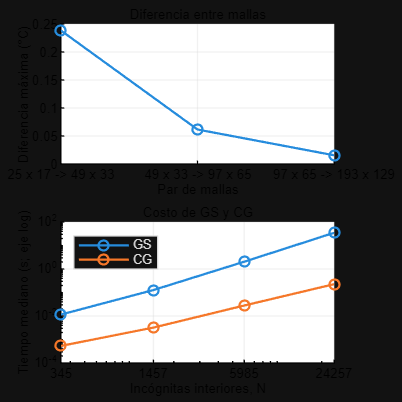

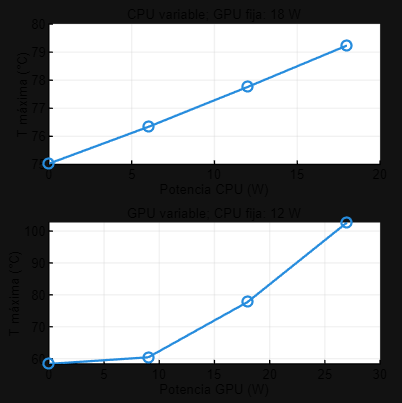

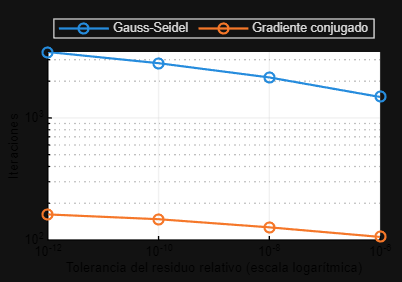


archivosFiguras = graficar_experimentos(carpetaCorrida);

## Registro de corrida y validación

Se guardan el identificador, la versión de MATLAB, los parámetros y la ruta del Live Script unificado ejecutado, junto con mediciones de tiempo y estado de validación.

metadatosCorrida = struct('run_id',identificadorCorrida, ...
    'matlab_release',version('-release'),'matlab_version',version, ...
    'run_started_local',char(datetime('now','Format','yyyy-MM-dd''T''HH:mm:ssXXX')),...
    'baseline_grid',cfg.baselineGrid,'unknowns',modelo.nUnknowns, ...
    'tolerance',cfg.tolerance,'cpu_power_W',cfg.cpu.power,'gpu_power_W',cfg.gpu.power, ...
    'direct_reference_Tmax_C',metricasDirectas.Tmax_C, ...
    'gauss_seidel_iterations',gaussSeidel.iterations, ...
    'cg_iterations',gradienteConjugado.iterations, ...
    'direct_solve_time_s',tiempoDirecto_s,'experiments_wall_time_s',tiempoExperimentos_s, ...
    'executed_live_script',archivoLive);
escribir_json(fullfile(carpetaCorrida,'run_metadata.json'),metadatosCorrida);
comandoEjecucion = sprintf('matlab -batch "setappdata(0,''MN_Grupo4_liveScriptPath'',''%s''); run(''%s'')"', ...
    strrep(archivoLive,'\','\\'),strrep(archivoLive,'\','\\'));
evidencia = struct('baseStatus','passed','baseTime_s',tiempoDirecto_s, ...
    'experimentsStatus','passed','experimentsTime_s',tiempoExperimentos_s, ...
    'experimentScript',archivoLive,'command',comandoEjecucion, ...
    'mlxStatus','passed','mlxCommand',comandoEjecucion, ...
    'fullMlxStatus','passed','fullMlxCommand',comandoEjecucion);
reporteValidacion = generar_reporte_validacion( ...
    fullfile(carpetaCorrida,'resultados'), ...
    fullfile(carpetaCorrida,'reporte_validacion.json'), evidencia);
assert(strcmp(reporteValidacion.validation_status,'passed'));
rutaRelativaResultados = fullfile('resultados', identificadorCorrida);
fprintf('Validación: %s. Resultados guardados en %s\n', ...
    reporteValidacion.validation_status, rutaRelativaResultados);

Validación: passed. Resultados guardados en resultados\run_20261024_094841_539fe69e-a9e4-4deb-ae8e-fd0336be0328


## Funciones locales

Las funciones siguientes integran configuración, discretización, métodos iterativos, métricas, experimentos, validaciones, exportación y gráficas en este único Live Script; se mantienen al final del archivo.

function cfg = configuracion_modelo(ajustes)
%CONFIGURACION_MODELO Valida los parámetros del modelo térmico.
% Se usan unidades SI, salvo la temperatura, que se informa en °C. Los parámetros son
% supuestos de la simulación y no mediciones de un equipo real.
    if nargin < 1 || isempty(ajustes), ajustes = struct(); end
    cfg = struct( ...
        'Lx',0.24,'Ly',0.16,'thickness',0.002,'k',50,'Tb',25, ...
        'cpu',struct('x',0.04,'y',0.08,'width',0.04,'height',0.04,'power',12), ...
        'gpu',struct('x',0.16,'y',0.08,'width',0.04,'height',0.04,'power',18), ...
        'grids',[25 17;49 33;97 65;193 129], ...
        'baselineGrid',[49 33],'tolerance',1e-8,'maxIterations',200000, ...
        'initialTemperature',25,'checkpointFractions',[0.01 0.1 0.5 1], ...
        'assumptions',{{'Placa homogénea e isotrópica','Conducción estacionaria bidimensional', ...
            'Conductividad constante','Fuentes rectangulares uniformes','Temperatura de borde fija'}});
    cfg = merge_struct(cfg,ajustes);
    validate_config(cfg);
end

function out = merge_struct(base, update)
    out = base;
    names = fieldnames(update);
    for q = 1:numel(names)
        key = names{q};
        if isstruct(update.(key)) && isfield(base,key) && isstruct(base.(key))
            out.(key) = merge_struct(base.(key),update.(key));
        else
            out.(key) = update.(key);
        end
    end
end

function validate_config(c)
    required = {'Lx','Ly','thickness','k','Tb','cpu','gpu','grids', ...
        'baselineGrid','tolerance','maxIterations','initialTemperature', ...
        'checkpointFractions'};
    assert(all(isfield(c,required)), ...
        'Falta uno o más campos requeridos de configuración del modelo.');
    positive = [c.Lx c.Ly c.thickness c.k c.cpu.width c.cpu.height ...
        c.gpu.width c.gpu.height];
    assert(all(isfinite(positive)) && all(positive > 0), ...
        'Las dimensiones, el espesor y la conductividad deben ser finitos y positivos.');
    assert(isfinite(c.Tb) && isfinite(c.cpu.power) && isfinite(c.gpu.power), ...
        'La temperatura y las potencias deben ser finitas.');
    rects = [c.cpu.x c.cpu.y c.cpu.width c.cpu.height; ...
             c.gpu.x c.gpu.y c.gpu.width c.gpu.height];
    assert(all(isfinite(rects),'all'), 'Las coordenadas de las fuentes deben ser finitas.');
    assert(all(rects(:,1) >= 0 & rects(:,2) >= 0 & ...
        rects(:,1)+rects(:,3) <= c.Lx & rects(:,2)+rects(:,4) <= c.Ly), ...
        'Cada fuente rectangular debe estar dentro de la placa.');
    overlapX = min(rects(1,1)+rects(1,3),rects(2,1)+rects(2,3)) - ...
        max(rects(1,1),rects(2,1));
    overlapY = min(rects(1,2)+rects(1,4),rects(2,2)+rects(2,4)) - ...
        max(rects(1,2),rects(2,2));
    assert(overlapX <= 0 || overlapY <= 0, 'Las regiones de CPU y GPU no deben superponerse.');
    assert(size(c.grids,2)==2 && all(c.grids(:)>=3) && all(mod(c.grids(:)-1,2)==0), ...
        'Cada dimensión de malla debe contar al menos 3 nodos y un número impar de intervalos.');
    assert(all(isfinite(c.grids),'all') && all(c.grids(:)==floor(c.grids(:))), ...
        'Las dimensiones de la malla deben ser enteros finitos.');
    assert(isnumeric(c.baselineGrid) && numel(c.baselineGrid)==2 && ...
        all(isfinite(c.baselineGrid)) && all(c.baselineGrid>=3) && ...
        all(c.baselineGrid==floor(c.baselineGrid)), ...
        'baselineGrid debe contener dos cantidades enteras finitas de nodos, ambas de al menos 3.');
    assert(isfinite(c.tolerance) && c.tolerance>0, ...
        'La tolerancia del método debe ser positiva y finita.');
    assert(isfinite(c.maxIterations) && c.maxIterations>=1 && ...
        c.maxIterations==floor(c.maxIterations), ...
        'maxIterations debe ser un entero positivo.');
    assert(isfinite(c.initialTemperature), ...
        'La temperatura inicial debe ser finita.');
    assert(isnumeric(c.checkpointFractions) && ...
        all(isfinite(c.checkpointFractions)) && ...
        all(c.checkpointFractions>=0 & c.checkpointFractions<=1), ...
        'Las fracciones de control deben ser valores finitos en [0,1].');
end


function cfg = planteamiento_modelo()
%PLANTEAMIENTO_MODELO Devuelve los parámetros del modelo en unidades SI.
% Los parámetros quedan en MATLAB para que no se necesite un JSON externo.
    cfg = configuracion_modelo();
end


function model = discretizacion_matriz(cfg, nx, ny)
%DISCRETIZACION_MATRIZ Ensambla el sistema disperso de diferencias finitas.
% La función devuelve A y b para
% -laplaciano(T)=q'''/k con temperatura de borde fija CFG.Tb. Las longitudes
% se expresan en metros, la conductividad en W/(m K) y la potencia en W;
% la temperatura se informa en °C. NX y NY incluyen los nodos de borde.
% Las incógnitas son nodos interiores en orden por columnas de MATLAB (y varía más rápido).
% La fuente de cada nodo interior se promedia en su volumen de control dual. Las
% fracciones de solapamiento entre rectángulos y volúmenes de control conservan la potencia integrada, incluso
% cuando los bordes de las fuentes quedan entre nodos de la malla.
    if nargin < 2 || isempty(nx), nx = cfg.baselineGrid(1); end
    if nargin < 3 || isempty(ny), ny = cfg.baselineGrid(2); end
    validateattributes(nx,{'numeric'},{'scalar','integer','>=',3});
    validateattributes(ny,{'numeric'},{'scalar','integer','>=',3});
    validateattributes(cfg.Lx,{'numeric'},{'scalar','real','finite','positive'});
    validateattributes(cfg.Ly,{'numeric'},{'scalar','real','finite','positive'});
    validateattributes(cfg.k,{'numeric'},{'scalar','real','finite','positive'});
    validateattributes(cfg.thickness,{'numeric'},{'scalar','real','finite','positive'});
    x = linspace(0,cfg.Lx,nx); y = linspace(0,cfg.Ly,ny);
    dx=x(2)-x(1); dy=y(2)-y(1); nxi=nx-2; nyi=ny-2;
    xlo=x(2:end-1)-dx/2; xhi=x(2:end-1)+dx/2;
    ylo=y(2:end-1)-dy/2; yhi=y(2:end-1)+dy/2;
    q = zeros(nyi,nxi); sourcePower = struct();
    names = {'cpu','gpu'};
    for s=1:numel(names)
        name=names{s}; r=cfg.(name);
        assert(r.x>=xlo(1) && r.x+r.width<=xhi(end) && ...
            r.y>=ylo(1) && r.y+r.height<=yhi(end), ...
            'Las fuentes deben quedar dentro de los volúmenes de control interiores activos.');
        qvol = r.power/(r.width*r.height*cfg.thickness);
        overlapX=max(0,min(xhi,r.x+r.width)-max(xlo,r.x));
        overlapY=max(0,min(yhi,r.y+r.height)-max(ylo,r.y));
        overlapArea=overlapY(:)*overlapX(:)';
        quadratureFactor=overlapArea/(dx*dy);
        q=q+qvol*quadratureFactor;
        sourcePower.(name)=sum(qvol*overlapArea,'all')*cfg.thickness;
    end
    % A*T=b, donde A aproxima -laplaciano. Las contribuciones Dirichlet se
    % trasladan a b; el término fuente del lado derecho es q'''/k.
    % El ensamblaje de Kronecker sigue el orden por columnas de MATLAB:
    % reshape(T,nyi,nxi) hace que y sea el índice más rápido del vector.
    Tx = spdiags([-ones(nxi,1)/dx^2, 2*ones(nxi,1)/dx^2, ...
        -ones(nxi,1)/dx^2],[-1 0 1],nxi,nxi);
    Ty = spdiags([-ones(nyi,1)/dy^2, 2*ones(nyi,1)/dy^2, ...
        -ones(nyi,1)/dy^2],[-1 0 1],nyi,nyi);
    A = kron(speye(nxi),Ty) + kron(Tx,speye(nyi));
    rhs = q(:)/cfg.k;
    boundary = zeros(nyi,nxi);
    boundary(:,1)=boundary(:,1)+cfg.Tb/dx^2;
    boundary(:,end)=boundary(:,end)+cfg.Tb/dx^2;
    boundary(1,:)=boundary(1,:)+cfg.Tb/dy^2;
    boundary(end,:)=boundary(end,:)+cfg.Tb/dy^2;
    b=rhs+boundary(:);
    model=struct('cfg',cfg,'nx',nx,'ny',ny,'x',x,'y',y,'dx',dx,'dy',dy, ...
        'nUnknowns',nxi*nyi,'A',A,'b',b,'sourceQ',q,'sourceTerm',rhs, ...
        'sourcePower',sourcePower,'symmetryError',norm(A-A','fro')/max(1,norm(A,'fro')));
end


function valor = residuo_relativo(A,b,x)
% Residuo relativo 2-norm; si b es cero, el denominador se toma como uno.
    denominador=norm(b,2);
    if denominador==0, denominador=1; end
    valor=norm(b-A*x,2)/denominador;
end

function out = metodo_gauss_seidel(A,b,x0,opts)
%METODO_GAUSS_SEIDEL Iteración explícita de Gauss-Seidel en orden lexicográfico.
% Se usa la convención del curso A=D-L-U, con L=-tril(A,-1) y
% U=-triu(A,1), por lo que (D-L)*x_new = U*x_old+b. El sistema triangular inferior
% disperso se resuelve directamente, sin formar una inversa. opts puede
% incluir tolerance, maxIterations, residualCheckInterval y
% checkpointFractions. El residuo devuelto es ||b-A*x||_2/||b||_2
% (se usa denominador uno solo si b es exactamente cero).
    if nargin<4, opts=struct(); end
    opts=solver_options(opts); n=numel(b); x=x0(:);
    assert(isequal(size(A),[n n]) && numel(x)==n,'Las dimensiones de A, b y x0 no coinciden.');
    d=diag(A); assert(all(isfinite(d))&&all(d~=0),'A tiene una diagonal nula o no finita.');
    D=spdiags(d,0,n,n);
    L=-tril(A,-1);
    U=-triu(A,1);
    M=D-L;
    checkpoints=iteration_checkpoints(opts);
    history=nan(opts.maxIterations+1,1); history(1)=residuo_relativo(A,b,x);
    states=struct('iter',{},'x',{}); states(1)=struct('iter',0,'x',x);
    stepHistory=nan(opts.maxIterations,1);
    if history(1)<=opts.tolerance, out=finish('converged',0,0); return; end
    status='max_iterations'; t=tic;
    for iter=1:opts.maxIterations
        xOld=x;
        x=M\(U*x+b);
        stepNorm=norm(x-xOld,inf);
        currentNorm=norm(x,inf);
        if currentNorm==0
            if stepNorm==0, stepHistory(iter)=0; else, stepHistory(iter)=Inf; end
        else
            stepHistory(iter)=stepNorm/currentNorm;
        end
        if mod(iter,opts.residualCheckInterval)==0 || iter==opts.maxIterations || any(checkpoints==iter)
            rel=residuo_relativo(A,b,x);
            history(iter+1)=rel;
            if any(checkpoints==iter), states(end+1)=struct('iter',iter,'x',x); end %#ok<AGROW>
            if ~isfinite(rel) || any(~isfinite(x)), status='nonfinite'; break; end
            if rel<=opts.tolerance, status='converged'; break; end
        end
    end
    elapsed=toc(t); nDone=iter;
    history=history(1:nDone+1);
    if states(end).iter~=nDone, states(end+1)=struct('iter',nDone,'x',x); end
    out=struct('solver','Gauss-Seidel','x',x,'iterations',nDone, ...
        'relativeResidual',residuo_relativo(A,b,x),'time_s',elapsed,'status',status, ...
        'history',history,'states',states,'tolerance',opts.tolerance, ...
        'relativeStepError',stepHistory(nDone), ...
        'relativeStepErrorHistory',stepHistory(1:nDone));
    function o=finish(st,it,tm)
        o=struct('solver','Gauss-Seidel','x',x,'iterations',it, ...
            'relativeResidual',history(1),'time_s',tm,'status',st, ...
            'history',history(1),'states',states,'tolerance',opts.tolerance, ...
            'relativeStepError',NaN,'relativeStepErrorHistory',[]);
    end
end

function o=solver_options(o)
    defaults=struct('tolerance',1e-8,'maxIterations',200000, ...
        'checkpointFractions',[0.01 0.1 0.5 1],'residualCheckInterval',1);
    f=fieldnames(defaults); for j=1:numel(f), if ~isfield(o,f{j}),o.(f{j})=defaults.(f{j});end,end
    validateattributes(o.tolerance,{'numeric'},{'scalar','real','finite','positive'});
    validateattributes(o.maxIterations,{'numeric'},{'scalar','real','finite','integer','>=',1});
    validateattributes(o.residualCheckInterval,{'numeric'},{'scalar','real','finite','integer','>=',1});
    validateattributes(o.checkpointFractions,{'numeric'},{'vector','real','finite','>=',0,'<=',1});
    assert(o.maxIterations>=1 && o.maxIterations==floor(o.maxIterations), ...
        'maxIterations debe ser un entero positivo.');
end

function checkpoints=iteration_checkpoints(opts)
% Incluye las iteraciones inicial y final para registrar los extremos de cada ejecución.
    checkpoints=unique([0 round(opts.checkpointFractions(:)'*opts.maxIterations) ...
        opts.maxIterations]);
end


function [z] = gausseidel_profesor(A,b,x0,Tol)
%GAUSSEIDEL_PROFESOR Implementación literal entregada en el laboratorio.
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);
    Tgs = inv(D-L)*U;
    cgs = inv(D-L)*b;
    error = 1;
    z = [x0' error];
    while error > Tol
        x1 = Tgs*x0 + cgs;
        error = norm(x1-x0,'inf')/norm(x1,'inf');
        z = [z; x1' error];
        x0 = x1;
    end
end


function out = metodo_gradiente_conjugado(A,b,x0,opts)
%METODO_GRADIENTE_CONJUGADO Gradiente Conjugado explícito sin precondicionar.
% Resuelve el sistema disperso, simétrico y definido positivo sin llamar a
% pcg. opts puede incluir tolerance, maxIterations y checkpointFractions.
% El residuo informado es ||b-A*x||_2/||b||_2; si b es cero se usa uno.
% Si el residuo recursivo alcanza la tolerancia, se verifica el residuo real.
% Si no cumple, se reinicia CG con r=b-A*x para conservar la validez matemática.
% La rutina comprueba curvatura positiva y valores no finitos.
    if nargin<4, opts=struct(); end
    opts=solver_options_cg(opts); n=numel(b); x=x0(:);
    assert(isequal(size(A),[n n]) && numel(x)==n,'Las dimensiones de A, b y x0 no coinciden.');
    bn=norm(b,2); if bn==0,bn=1;end
    r=b-A*x; p=r; rr=r'*r; rel=norm(r,2)/bn;
    history=nan(opts.maxIterations+1,1); history(1)=rel;
    checkpoints=iteration_checkpoints_cg(opts);
    states=struct('iter',0,'x',x); status='max_iterations';
    if rel<=opts.tolerance
        relExact=residuo_relativo(A,b,x);
        history(1)=relExact;
        if relExact<=opts.tolerance
            out=struct('solver','Conjugate Gradient','x',x,'iterations',0, ...
                'relativeResidual',relExact,'time_s',0,'status','converged', ...
                'history',history(1),'states',states,'tolerance',opts.tolerance, ...
                'relativeStepError',NaN); return;
        end
        r=b-A*x; p=r; rr=r'*r; rel=norm(r,2)/bn;
        history(1)=rel;
    end
    t=tic; nDone=0;
    for iter=1:opts.maxIterations
        Ap=A*p; curvature=p'*Ap;
        if ~isfinite(curvature) || curvature<=0, status='nonpositive_curvature'; break; end
        alpha=rr/curvature; x=x+alpha*p; nDone=iter; r=r-alpha*Ap;
        rrNew=r'*r; rel=norm(r,2)/bn; history(iter+1)=rel;
        if any(checkpoints==iter), states(end+1)=struct('iter',iter,'x',x); end %#ok<AGROW>
        if ~isfinite(rel) || any(~isfinite(x)), status='nonfinite'; break; end
        if rel<=opts.tolerance
            relExact=residuo_relativo(A,b,x);
            history(iter+1)=relExact;
            if relExact<=opts.tolerance
                status='converged'; break;
            end
            % Residual replacement restarts CG from this iterate after drift.
            r=b-A*x; rrNew=r'*r; rel=norm(r,2)/bn;
            if ~isfinite(rel) || any(~isfinite(r)), status='nonfinite'; break; end
            p=r; rr=rrNew;
            continue;
        end
        if rr==0, status='zero_residual_breakdown'; break; end
        beta=rrNew/rr; p=r+beta*p; rr=rrNew;
    end
    elapsed=toc(t); history=history(1:nDone+1);
    relExact=residuo_relativo(A,b,x);
    if states(end).iter~=nDone, states(end+1)=struct('iter',nDone,'x',x); end
    out=struct('solver','Conjugate Gradient','x',x,'iterations',nDone, ...
        'relativeResidual',relExact,'time_s',elapsed,'status',status, ...
        'history',history,'states',states,'tolerance',opts.tolerance, ...
        'relativeStepError',NaN);
end

function o=solver_options_cg(o)
    defaults=struct('tolerance',1e-8,'maxIterations',200000, ...
        'checkpointFractions',[0.01 0.1 0.5 1]);
    f=fieldnames(defaults); for j=1:numel(f), if ~isfield(o,f{j}),o.(f{j})=defaults.(f{j});end,end
    validateattributes(o.tolerance,{'numeric'},{'scalar','real','finite','positive'});
    validateattributes(o.maxIterations,{'numeric'},{'scalar','real','finite','integer','>=',1});
    validateattributes(o.checkpointFractions,{'numeric'},{'vector','real','finite','>=',0,'<=',1});
end

function checkpoints=iteration_checkpoints_cg(opts)
% Incluye las iteraciones inicial y final para registrar los extremos de cada ejecución.
    checkpoints=unique([0 round(opts.checkpointFractions(:)'*opts.maxIterations) ...
        opts.maxIterations]);
end


function field = campo_temperatura(model, interior)
%CAMPO_TEMPERATURA Reconstruye el campo nodal completo de temperatura.
    T=model.cfg.Tb*ones(model.ny,model.nx);
    T(2:end-1,2:end-1)=reshape(interior,model.ny-2,model.nx-2);
    q=zeros(model.ny,model.nx);
    q(2:end-1,2:end-1)=model.sourceQ;
    [X,Y]=meshgrid(model.x,model.y);
    field=table(X(:),Y(:),T(:),q(:),'VariableNames', ...
        {'x_m','y_m','T_C','q_W_m3'});
end


function m = metricas_temperatura(model,x)
%METRICAS_TEMPERATURA Calcula máximo térmico y residuo relativo.
    T=model.cfg.Tb*ones(model.ny,model.nx);
    T(2:end-1,2:end-1)=reshape(x,model.ny-2,model.nx-2);
    maxT=max(T,[],'all'); [iy,ix]=find(T==maxT);
    m=struct('Tmax_C',maxT,'hotspot_x_m',model.x(ix(1)), ...
        'hotspot_y_m',model.y(iy(1)), ...
        'relative_residual',residuo_relativo(model.A,model.b,x), ...
        'finite',all(isfinite(T),'all'));
end


function tabla = comparacion_metodos(modelo, solucion_directa, gauss_seidel, gradiente_conjugado)
%COMPARACION_METODOS Resume errores algebraicos respecto al vector directo.
    directa = metricas_temperatura(modelo,solucion_directa);
    gs = metricas_temperatura(modelo,gauss_seidel.x);
    cg = metricas_temperatura(modelo,gradiente_conjugado.x);
    residuo_directo = residuo_relativo(modelo.A,modelo.b,solucion_directa);
    errorAlgebraico = [0; max(abs(gauss_seidel.x(:)-solucion_directa(:))); ...
        max(abs(gradiente_conjugado.x(:)-solucion_directa(:)))];
    errorIterativo = ["No aplica (referencia)"; ...
        compose('%.3e',gauss_seidel.relativeStepError); "No aplica"];
    tabla = table( ...
        ["Referencia directa"; string(gauss_seidel.solver); string(gradiente_conjugado.solver)], ...
        [0; gauss_seidel.iterations; gradiente_conjugado.iterations], ...
        [residuo_directo; gauss_seidel.relativeResidual; gradiente_conjugado.relativeResidual], ...
        [directa.Tmax_C; gs.Tmax_C; cg.Tmax_C], errorAlgebraico, errorIterativo, ...
        'VariableNames',{'metodo','iteraciones','residuo_relativo', ...
        'temperatura_maxima_C','error_algebraico_maximo_C','error_iterativo_relativo_GS'});
end


function report = experimentos(outputRoot, timingOptions)
%EXPERIMENTOS Ejecuta el caso base, el refinamiento, la sensibilidad y el estrés.
% TIMINGOPTIONS puede incluir warmupRuns y measuredRuns. Cada
% repetición medida parte del mismo vector inicial; su solución no
% reemplaza la solución ni el historial canónicos calculados abajo.
% La función calcula los experimentos y devuelve sus tablas y resultados.
    if nargin<1 || isempty(outputRoot)
        outputRoot=fullfile(fileparts(mfilename('fullpath')),'..','resultados');
    end
    if nargin<2 || isempty(timingOptions), timingOptions=struct(); end
    timingOptions=validate_timing_options(timingOptions);
    cfg=planteamiento_modelo();
    baseDir=fullfile(outputRoot,'escenario_base'); convDir=fullfile(outputRoot,'convergencia');
    refDir=fullfile(outputRoot,'refinamiento');
    senDir=fullfile(outputRoot,'sensibilidad'); stressDir=fullfile(outputRoot,'estres_numerico');
    dirs={baseDir,convDir,refDir,senDir,stressDir}; for i=1:numel(dirs),if ~isfolder(dirs{i}),mkdir(dirs{i});end,end

    % Escenario 1: mismos A, b y vector inicial constante para ambos métodos.
    nx=cfg.baselineGrid(1); ny=cfg.baselineGrid(2); model=discretizacion_matriz(cfg,nx,ny);
    x0=cfg.initialTemperature*ones(model.nUnknowns,1);
    directTimer=tic; xDirect=model.A\model.b; directTime=toc(directTimer);
    opts=struct('tolerance',cfg.tolerance,'maxIterations',cfg.maxIterations, ...
        'checkpointFractions',cfg.checkpointFractions);
    gs=metodo_gauss_seidel(model.A,model.b,x0,opts);
    cg=metodo_gradiente_conjugado(model.A,model.b,x0,opts);
    [baseTiming,baseTimingStats]=benchmark_solvers(model.A,model.b,x0,opts, ...
        nx,ny,"base",timingOptions);
    [directTiming,directTimingStats]=benchmark_direct(model.A,model.b,nx,ny, ...
        "base",timingOptions);
    baseTiming=[directTiming;baseTiming];
    writetable(baseTiming,fullfile(baseDir,'timing_repeats.csv'));
    mDirect=metricas_temperatura(model,xDirect);
    field=campo_temperatura(model,xDirect); writetable(field,fullfile(baseDir,'baseline_field.csv'));
    history=history_table({gs,cg}); writetable(history,fullfile(baseDir,'convergence_history.csv'));
    exportar_estados_representativos(model,{gs,cg}, ...
        fullfile(baseDir,'representative_states.csv'));
    mGs=metricas_temperatura(model,gs.x); mCg=metricas_temperatura(model,cg.x);
    summary=summary_table(model,{gs,cg},[mGs.Tmax_C mCg.Tmax_C],baseTimingStats);
    directRow=table("Sparse direct",cfg.tolerance,1,mDirect.relative_residual,NaN, ...
        directTimingStats.median_s,directTime,directTimingStats.median_s, ...
        directTimingStats.dispersion_s,directTimingStats.iqr_s, ...
        directTimingStats.measured_runs, ...
        nx,ny, ...
        model.nUnknowns,cfg.cpu.power,cfg.gpu.power,mDirect.Tmax_C,"reference", ...
        'VariableNames',summary.Properties.VariableNames);
    summary=[directRow;summary]; writetable(summary,fullfile(baseDir,'solver_summary.csv'));
    sourceInfo=source_manifest(cfg);
    metadata=struct('experiment_id','scenario_base','model','steady_2d_conduction_localized_sources', ...
        'geometry',struct('Lx_m',cfg.Lx,'Ly_m',cfg.Ly,'sources',sourceInfo), ...
        'thickness_m',cfg.thickness,'k_W_mK',cfg.k,'boundary_temperature_C',cfg.Tb, ...
        'cpu_power_W',cfg.cpu.power,'gpu_power_W',cfg.gpu.power, ...
        'cpu_q_W_m3',cfg.cpu.power/(cfg.cpu.width*cfg.cpu.height*cfg.thickness), ...
        'gpu_q_W_m3',cfg.gpu.power/(cfg.gpu.width*cfg.gpu.height*cfg.thickness), ...
        'materialized_source_power_W',model.sourcePower,'nx',nx,'ny',ny, ...
        'unknowns',model.nUnknowns,'dx_m',model.dx,'dy_m',model.dy, ...
        'tolerance',cfg.tolerance,'assumptions',{cfg.assumptions}, ...
        'initial_state_C',cfg.initialTemperature,'matrix_symmetry_relative_error',model.symmetryError, ...
        'timing_method',struct('warmup_runs',timingOptions.warmupRuns, ...
        'measured_runs',timingOptions.measuredRuns, ...
        'dispersion','desviación estándar muestral de los tiempos transcurridos informados por el método'), ...
        'matrix_spd_evidence','Verificado mediante simetría y factorización de Cholesky dispersa; la energía de Dirichlet es positiva para vectores interiores no nulos.');
    escribir_json(fullfile(baseDir,'metadata.json'),metadata);
    save(fullfile(baseDir,'baseline.mat'),'model','xDirect','gs','cg','metadata','-v7.3');
    write_manifest(baseDir,metadata,struct('field','baseline_field.csv', ...
        'history','convergence_history.csv','states','representative_states.csv', ...
        'mesh','solver_summary.csv','summary','solver_summary.csv', ...
        'timing','timing_repeats.csv','metadata','metadata.json','mat','baseline.mat'));
    % La carpeta de convergencia separa los historiales iterativos, mientras
    % el campo y el resumen corresponden al mismo caso base.
    copyfile(fullfile(baseDir,'convergence_history.csv'),fullfile(convDir,'convergence_history.csv'),'f');
    copyfile(fullfile(baseDir,'representative_states.csv'),fullfile(convDir,'representative_states.csv'),'f');
    convMeta=metadata; convMeta.experiment_id='iterative_convergence';
    convMeta.initial_state_C=cfg.initialTemperature;
    escribir_json(fullfile(convDir,'metadata.json'),convMeta);
    write_manifest(convDir,convMeta,struct('history','convergence_history.csv', ...
        'states','representative_states.csv','metadata','metadata.json'));

    % Escenario 3: mallas anidadas. La referencia directa dispersa en cada nivel separa
    % el error algebraico (iterativo frente a directo) del refinamiento espacial.
    refinement=table(); refinementTiming=table();
    refSol=cell(size(cfg.grids,1),1); refModels=cell(size(cfg.grids,1),1);
    for g=1:size(cfg.grids,1)
        gx=cfg.grids(g,1); gy=cfg.grids(g,2); mm=discretizacion_matriz(cfg,gx,gy);
        xd=mm.A\mm.b; md=metricas_temperatura(mm,xd); refSol{g}=reshape_field(mm,xd); refModels{g}=mm;
        ini=cfg.initialTemperature*ones(mm.nUnknowns,1);
        gg=metodo_gauss_seidel(mm.A,mm.b,ini,opts);
        cc=metodo_gradiente_conjugado(mm.A,mm.b,ini,opts);
        [meshTiming,meshTimingStats]=benchmark_solvers(mm.A,mm.b,ini,opts, ...
            gx,gy,"refinement",timingOptions);
        refinementTiming=[refinementTiming;meshTiming]; %#ok<AGROW>
        mg=metricas_temperatura(mm,gg.x); mc=metricas_temperatura(mm,cc.x);
        rows=summary_table(mm,{gg,cc},[mg.Tmax_C mc.Tmax_C],meshTimingStats);
        rows.spatial_max_abs_difference_C=NaN(height(rows),1);
        rows.algebraic_max_abs_error_C=[max(abs(gg.x-xd));max(abs(cc.x-xd))];
        rows.direct_reference_Tmax_C=repmat(md.Tmax_C,height(rows),1);
        rows.discrete_source_power_W=repmat(mm.sourcePower.cpu+mm.sourcePower.gpu,height(rows),1);
        refinement=[refinement;rows]; %#ok<AGROW>
    end
    for g=1:size(cfg.grids,1)-1
        coarse=refSol{g}; fine=refSol{g+1}; cm=refModels{g}; fm=refModels{g+1};
        [Xc,Yc]=meshgrid(cm.x,cm.y); [Xf,Yf]=meshgrid(fm.x,fm.y);
        fineAtCoarse=interp2(Xf,Yf,fine,Xc,Yc,'linear');
        delta=max(abs(coarse-fineAtCoarse),[],'all');
        idx=(g-1)*2+(1:2); refinement.spatial_max_abs_difference_C(idx)=delta;
    end
    writetable(refinement,fullfile(refDir,'refinement.csv'));
    writetable(refinementTiming,fullfile(refDir,'timing_repeats.csv'));
    refMeta=struct('experiment_id','mesh_refinement','comparison','Máxima diferencia nodal absoluta: cada campo directo de malla gruesa frente a la interpolación bilineal del campo directo de la siguiente malla fina', ...
        'geometry',metadata.geometry,'tolerance',cfg.tolerance);
    escribir_json(fullfile(refDir,'metadata.json'),refMeta);
    refMeta.timing_method=metadata.timing_method;
    write_manifest(refDir,refMeta,struct('mesh','refinement.csv', ...
        'timing','timing_repeats.csv','metadata','metadata.json'));

    % Escenario 4: se varía cada fuente por separado; la solución directa aísla
    % la respuesta física del modelo del error de parada iterativa.
    scales=[0 0.5 1 1.5]; sensitivity=table();
    for s=1:numel(scales)
        for sourceIdx=1:2
            variant=cfg; sourceName={'cpu','gpu'}; sourceName=sourceName{sourceIdx};
            variant.(sourceName).power=cfg.(sourceName).power*scales(s);
            sm=discretizacion_matriz(variant,nx,ny); sx=sm.A\sm.b; mt=metricas_temperatura(sm,sx);
            sensitivity=[sensitivity;table(string(sourceName),scales(s),variant.cpu.power,variant.gpu.power, ...
                mt.Tmax_C,mt.hotspot_x_m,mt.hotspot_y_m,mt.relative_residual, ...
                'VariableNames',{'varied_source','scale','cpu_power_W','gpu_power_W','Tmax_C', ...
                'hotspot_x_m','hotspot_y_m','rel_residual'})]; %#ok<AGROW>
        end
    end
    writetable(sensitivity,fullfile(senDir,'sensitivity.csv'));
    senMeta=struct('experiment_id','source_sensitivity','geometry',metadata.geometry, ...
        'scales',[scales],'procedure','Variar por separado la potencia de CPU o GPU; mantener fija la otra fuente y los demás parámetros.');
    escribir_json(fullfile(senDir,'metadata.json'),senMeta);
    write_manifest(senDir,senMeta,struct('sensitivity','sensitivity.csv','metadata','metadata.json'));

    % Escenario 5: barrido de tolerancias y casos extremos o
    % no físicos. Son pruebas de estrés numérico, no datos de un equipo real.
    stress=table(); stressTiming=table(); tolList=[1e-6 1e-8 1e-10 1e-12];
    for tol=tolList
        so=opts; so.tolerance=tol; so.maxIterations=max(cfg.maxIterations,100000);
        [repeatRows,repeatStats]=benchmark_solvers(model.A,model.b,x0,so, ...
            nx,ny,"baseline_tolerance",timingOptions);
        stressTiming=[stressTiming;repeatRows]; %#ok<AGROW>
        for alg=1:2
            if alg==1, rr=metodo_gauss_seidel(model.A,model.b,x0,so); else,rr=metodo_gradiente_conjugado(model.A,model.b,x0,so);end
            stress=[stress;stress_row("baseline_tolerance",tol,rr,repeatStats(alg))]; %#ok<AGROW>
        end
    end
    cases={"extreme_positive_1000x",1000,1000;"nonphysical_negative_cpu",-1,1};
    for c=1:size(cases,1)
        variant=cfg; variant.cpu.power=cfg.cpu.power*cases{c,2}; variant.gpu.power=cfg.gpu.power*cases{c,3};
        sm=discretizacion_matriz(variant,nx,ny); xx0=variant.initialTemperature*ones(sm.nUnknowns,1);
        so=opts; so.tolerance=1e-8;
        [repeatRows,repeatStats]=benchmark_solvers(sm.A,sm.b,xx0,so, ...
            nx,ny,string(cases{c,1}),timingOptions);
        stressTiming=[stressTiming;repeatRows]; %#ok<AGROW>
        for alg=1:2
            if alg==1,rr=metodo_gauss_seidel(sm.A,sm.b,xx0,so);else,rr=metodo_gradiente_conjugado(sm.A,sm.b,xx0,so);end
            stress=[stress;stress_row(cases{c,1},so.tolerance,rr,repeatStats(alg))]; %#ok<AGROW>
        end
    end
    writetable(stress,fullfile(stressDir,'stress.csv'));
    writetable(stressTiming,fullfile(stressDir,'timing_repeats.csv'));
    stressMeta=struct('experiment_id','numerical_stress','geometry',metadata.geometry, ...
        'timing_method',metadata.timing_method, ...
        'warning','Las potencias extremas y negativas son pruebas numéricas deliberadamente no físicas, no estimaciones de un equipo.');
    escribir_json(fullfile(stressDir,'metadata.json'),stressMeta);
    write_manifest(stressDir,stressMeta,struct('stress','stress.csv', ...
        'timing','timing_repeats.csv','metadata','metadata.json'));
    report=struct('baseDirectory',baseDir,'refinement',refinement,'sensitivity',sensitivity,'stress',stress);
end

function H=history_table(results)
    H=table();
    for a=1:numel(results)
        r=results{a}; H=[H;table((0:numel(r.history)-1)',repmat(string(r.solver),numel(r.history),1), ...
            r.history(:),'VariableNames',{'iter','solver','rel_residual'})]; %#ok<AGROW>
    end
end
function S=summary_table(m,results,tmax,timingStats)
    S=table();
    for j=1:numel(results)
        r=results{j}; timing=timingStats(j);
        S=[S;table(string(r.solver),r.tolerance,r.iterations,r.relativeResidual, ...
            r.relativeStepError, ...
            timing.median_s,r.time_s,timing.median_s,timing.dispersion_s, ...
            timing.iqr_s,timing.measured_runs,m.nx,m.ny,m.nUnknowns,m.cfg.cpu.power, ...
            m.cfg.gpu.power,tmax(j),string(r.status), ...
            'VariableNames',{'solver','tolerance','iter','rel_residual','rel_step_error','time_s', ...
            'canonical_time_s','time_median_s','time_std_s','time_iqr_s','timing_repeats', ...
            'nx','ny','unknowns','cpu_power_W','gpu_power_W','Tmax_C','status'})]; %#ok<AGROW>
    end
end

function options=validate_timing_options(options)
% El protocolo predeterminado usa una repetición de calentamiento y tres mediciones.
    defaults=struct('warmupRuns',1,'measuredRuns',3);
    names=fieldnames(defaults);
    for k=1:numel(names)
        if ~isfield(options,names{k}), options.(names{k})=defaults.(names{k}); end
        validateattributes(options.(names{k}),{'numeric'}, ...
            {'scalar','real','finite','integer','>=',0});
    end
    assert(options.measuredRuns>=3, ...
        'Se requieren al menos tres repeticiones medidas para resumir los tiempos.');
end

function [rows,stats]=benchmark_solvers(A,b,x0,opts,nx,ny,experiment,options)
% Mide cada método iterativo explícito sin conservar las soluciones de prueba.
    labels={"Gauss-Seidel","Conjugate Gradient"};
    rows=table(); stats=repmat(struct('median_s',NaN,'dispersion_s',NaN, ...
        'iqr_s',NaN, ...
        'measured_runs',options.measuredRuns),numel(labels),1);
    for alg=1:numel(labels)
        samples=zeros(options.measuredRuns,1);
        for run=1:options.warmupRuns
            execute_solver(alg,A,b,x0,opts); %#ok<NASGU>
        end
        for run=1:options.measuredRuns
            result=execute_solver(alg,A,b,x0,opts);
            samples(run)=result.time_s;
            rows=[rows;table(string(experiment),labels{alg},nx,ny,numel(b), ...
                "measured",run,result.time_s,result.iterations, ...
                result.relativeResidual,string(result.status), ...
                'VariableNames',{'experiment','solver','nx','ny','unknowns', ...
                'run_type','repetition','time_s','iterations','relative_residual','status'})]; %#ok<AGROW>
        end
        stats(alg).median_s=median(samples);
        stats(alg).dispersion_s=std(samples,0);
        stats(alg).iqr_s=iqr(samples);
    end
end

function [rows,stats]=benchmark_direct(A,b,nx,ny,experiment,options)
% Repite la solución directa dispersa con el mismo protocolo de medición.
    samples=zeros(options.measuredRuns,1);
    rows=table();
    for run=1:options.warmupRuns
        warmupSolution=A\b; %#ok<NASGU>
    end
    for run=1:options.measuredRuns
        timer=tic; x=A\b; elapsed=toc(timer);
        samples(run)=elapsed;
        residual=residuo_relativo(A,b,x);
        rows=[rows;table(string(experiment),"Sparse direct",nx,ny,numel(b), ...
            "measured",run,elapsed,1,residual,"reference", ...
            'VariableNames',{'experiment','solver','nx','ny','unknowns', ...
            'run_type','repetition','time_s','iterations','relative_residual','status'})]; %#ok<AGROW>
    end
    stats=struct('median_s',median(samples),'dispersion_s',std(samples,0), ...
        'iqr_s',iqr(samples), ...
        'measured_runs',options.measuredRuns);
end

function result=execute_solver(algorithm,A,b,x0,opts)
% La selección explícita permite relacionar cada medición con su método.
    if algorithm==1
        result=metodo_gauss_seidel(A,b,x0,opts);
    else
        result=metodo_gradiente_conjugado(A,b,x0,opts);
    end
end
function T=reshape_field(m,x)
    T=m.cfg.Tb*ones(m.ny,m.nx); T(2:end-1,2:end-1)=reshape(x,m.ny-2,m.nx-2);
end
function src=source_manifest(cfg)
    src=struct('name',{'CPU','GPU'},'x_m',{cfg.cpu.x,cfg.gpu.x}, ...
        'y_m',{cfg.cpu.y,cfg.gpu.y},'width_m',{cfg.cpu.width,cfg.gpu.width}, ...
        'height_m',{cfg.cpu.height,cfg.gpu.height});
end
function write_manifest(folder,metadata,datasets)
    names=fieldnames(datasets); entries=struct();
    for k=1:numel(names), entries.(names{k})=datasets.(names{k}); end
    manifest=struct('experiment_id',metadata.experiment_id,'metadata',metadata,'datasets',entries);
    escribir_json(fullfile(folder,'manifest.json'),manifest);
end
function r=stress_row(caseName,tol,s,timing)
    r=table(string(caseName),tol,string(s.solver),string(s.status),s.iterations, ...
        s.relativeResidual,timing.median_s,s.time_s,timing.median_s, ...
        timing.dispersion_s,timing.iqr_s,timing.measured_runs,'VariableNames', ...
        {'case','tol','solver','status','iterations','residual','time_s', ...
        'canonical_time_s','time_median_s','time_std_s','time_iqr_s','timing_repeats'});
end


function statesTable = exportar_estados_representativos(model, canonicalResults, outputPath)
%EXPORTAR_ESTADOS_REPRESENTATIVOS Exporta estados inicial, medio y final.
% Se conserva una repetición controlada: el punto medio depende del número
% canónico de iteraciones ya conocido y almacenarlo en cada paso gastaría memoria.
% Repite cada método explícito desde la misma condición inicial uniforme,
% con el número canónico de iteraciones como límite. El estado intermedio
% se define respecto a la duración real, no al límite configurado.
% La repetición debe converger a la solución canónica antes de que se
% exporte el campo. OUTPUTPATH es opcional; si se indica, se escribe un CSV.
%
% El índice de iteración cuenta pasos algebraicos del método; no es tiempo físico.

    if nargin < 3
        outputPath = '';
    end
    validateattributes(canonicalResults, {'cell'}, {'nonempty'});
    assert(isfield(model, 'cfg') && isfield(model.cfg, 'initialTemperature'), ...
        'El modelo debe incluir la temperatura inicial en model.cfg.');

    statesTable = table();
    [X, Y] = meshgrid(model.x, model.y);
    numberOfNodes = numel(X);
    initialVector = model.cfg.initialTemperature * ones(model.nUnknowns, 1);

    for index = 1:numel(canonicalResults)
        canonical = canonicalResults{index};
        options = struct('tolerance', canonical.tolerance, ...
            'maxIterations', canonical.iterations, 'checkpointFractions', 0.5);

        switch canonical.solver
            case 'Gauss-Seidel'
                replay = metodo_gauss_seidel(model.A, model.b, initialVector, options);
            case 'Conjugate Gradient'
                replay = metodo_gradiente_conjugado(model.A, model.b, initialVector, options);
            otherwise
                error('THERMOPLATE:UnknownSolver', ...
                    'No existe una repetición de estados para el método "%s".', canonical.solver);
        end

        assert(strcmp(replay.status, canonical.status) && ...
            replay.iterations == canonical.iterations, ...
            'La repetición de %s no coincide con el estado canónico.', canonical.solver);
        solutionScale = max(1, norm(canonical.x, inf));
        assert(norm(replay.x - canonical.x, inf) <= 100 * eps(solutionScale), ...
            'La solución repetida de %s difiere de la solución canónica.', canonical.solver);
        assert(numel(replay.states) == 3 && replay.states(1).iter == 0 && ...
            replay.states(2).iter > 0 && replay.states(3).iter == canonical.iterations, ...
            'La repetición de %s no produjo los estados inicial, medio y final.', canonical.solver);

        for stateIndex = 1:numel(replay.states)
            solverState = replay.states(stateIndex);
            temperature = model.cfg.Tb * ones(model.ny, model.nx);
            temperature(2:end-1, 2:end-1) = ...
                reshape(solverState.x, model.ny-2, model.nx-2);
            rows = table(repmat(solverState.iter, numberOfNodes, 1), ...
                repmat(string(canonical.solver), numberOfNodes, 1), ...
                X(:), Y(:), temperature(:), ...
                'VariableNames', {'iter', 'solver', 'x_m', 'y_m', 'T_C'});
            statesTable = [statesTable; rows]; %#ok<AGROW>
        end
    end

    if ~isempty(outputPath)
        writetable(statesTable, outputPath);
    end
end


function escribir_json(path,value)
%ESCRIBIR_JSON Escribe datos JSON en UTF-8.
    folder=fileparts(path); if ~isempty(folder)&&~isfolder(folder),mkdir(folder);end
    fid=fopen(path,'w','n','UTF-8'); assert(fid>=0,'No se puede abrir %s',path);
    cleaner=onCleanup(@()fclose(fid));
    fwrite(fid,jsonencode(value,'PrettyPrint',true),'char'); fwrite(fid,newline,'char');
end


function archivos = graficar_experimentos(ruta_simulacion)
%GRAFICAR_EXPERIMENTOS Exporta figuras A-D solo desde los CSV existentes.
    if nargin<1 || isempty(ruta_simulacion)
        ruta_simulacion=fileparts(fileparts(mfilename('fullpath')));
    end
    ruta_resultados=fullfile(ruta_simulacion,'resultados');
    ruta_figuras=fullfile(ruta_resultados,'figuras_matlab');
    if ~isfolder(ruta_figuras), mkdir(ruta_figuras); end
    set(groot,'defaultFigureColor','white','defaultAxesColor','white', ...
        'defaultAxesXColor','black','defaultAxesYColor','black', ...
        'defaultAxesGridColor',[0.78 0.78 0.78], ...
        'defaultTextColor','black');
    base=fullfile(ruta_resultados,'escenario_base');
    ref=fullfile(ruta_resultados,'refinamiento');
    sen=fullfile(ruta_resultados,'sensibilidad');
    stress=fullfile(ruta_resultados,'estres_numerico');
    hist=readtable(fullfile(base,'convergence_history.csv'),'VariableNamingRule','preserve');
    sol=readtable(fullfile(base,'solver_summary.csv'),'VariableNamingRule','preserve');
    refinement=readtable(fullfile(ref,'refinement.csv'),'VariableNamingRule','preserve');
    timing=readtable(fullfile(ref,'timing_repeats.csv'),'VariableNamingRule','preserve');
    sensitivity=readtable(fullfile(sen,'sensitivity.csv'),'VariableNamingRule','preserve');
    stressData=readtable(fullfile(stress,'stress.csv'),'VariableNamingRule','preserve');

    deg=char(176); a=char(225); iacute=char(237);

    % A1: campo espacial en una columna, con contorno, fuentes y máximo.
    f=figure('Name','Experimento A - campo','Color','w');
    tiledlayout(f,1,1,'TileSpacing','compact','Padding','compact');
    field=readtable(fullfile(base,'baseline_field.csv'),'VariableNamingRule','preserve');
    x=unique(field.x_m); y=unique(field.y_m);
    T=reshape(field.T_C,numel(y),numel(x));
    nexttile; imagesc(x,y,T); axis image xy; cb=colorbar; hold on
    cb.Label.String=['Temperatura (' deg 'C)']; cb.Label.FontSize=8; cb.Label.Color='k';
    cfg=planteamiento_modelo();
    rectangle('Position',[cfg.cpu.x cfg.cpu.y cfg.cpu.width cfg.cpu.height], ...
        'EdgeColor','w','LineWidth',1.2);
    rectangle('Position',[cfg.gpu.x cfg.gpu.y cfg.gpu.width cfg.gpu.height], ...
        'EdgeColor','w','LineWidth',1.2);
    rectangle('Position',[0 0 cfg.Lx cfg.Ly], ...
        'EdgeColor','w','LineStyle','--','LineWidth',1.0);
    text(cfg.cpu.x,cfg.cpu.y,' CPU','Color','w','FontWeight','bold','FontSize',8);
    text(cfg.gpu.x,cfg.gpu.y,' GPU','Color','w','FontWeight','bold','FontSize',8);
    [tm,im]=max(T(:)); [iy,ix]=ind2sub(size(T),im);
    plot(x(ix),y(iy),'wp','MarkerFaceColor','k','MarkerSize',8);
    text(x(ix)-0.008,y(iy)+0.018,sprintf('Temperatura máxima: %.2f %sC',tm,deg), ...
        'Color','k','BackgroundColor','w','Margin',1, ...
        'HorizontalAlignment','right','FontWeight','bold','FontSize',8);
    xlabel('x (m)'); ylabel('y (m)');
    exportar(f,fullfile(ruta_figuras,'experimento_A_campo.pdf'),3.35,2.45);

    % A2: un panel por método con escala vertical común.
    f=figure('Name','Experimento A - convergencia','Color','w');
    tiledlayout(f,2,1,'TileSpacing','compact','Padding','compact');
    solverNames={"Gauss-Seidel","Conjugate Gradient"};
    panelNames={'Gauss-Seidel','Gradiente conjugado'};
    legendNames={'GS','CG'};
    for k=1:2
        nexttile; hold on
        sel=string(hist.solver)==solverNames{k};
        niter=sol.iter(strcmp(sol.solver,solverNames{k}));
        semilogy(hist.iter(sel),hist.rel_residual(sel),'LineWidth',1.35, ...
            'DisplayName',sprintf('%s (%d iter.)',legendNames{k},niter));
        etiquetaTolerancia=sprintf('Tolerancia %.0e',sol.tolerance(1));
        yline(sol.tolerance(1),':k',etiquetaTolerancia, ...
            'LabelHorizontalAlignment','left','FontSize',7.5);
        set(gca,'YScale','log','YMinorGrid','off');
        ylim([sol.tolerance(1)/100 max(hist.rel_residual(sel))]);
        grid on; xlabel('Iteraciones'); ylabel('Residuo relativo');
        title(panelNames{k},'FontSize',8,'FontWeight','normal');
    end
    exportar(f,fullfile(ruta_figuras,'experimento_A_convergencia.pdf'),3.35,3.25);

    % B: paneles apilados al ancho de una columna.
    f=figure('Name','Experimento B - refinamiento','Color','w');
    tiledlayout(f,2,1,'TileSpacing','compact','Padding','compact');
    grids=unique(refinement(:,{'nx','ny','unknowns'}),'rows','stable');
    nexttile; hold on
    yy=[];
    for k=1:height(grids)-1
        row=find(refinement.nx==grids.nx(k) & refinement.ny==grids.ny(k),1);
        yy(end+1)=refinement.spatial_max_abs_difference_C(row); %#ok<AGROW>
    end
    plot(1:numel(yy),yy,'o-','LineWidth',1.35);
    etiquetasPares=compose('%d x %d -> %d x %d',grids.nx(1:end-1), ...
        grids.ny(1:end-1),grids.nx(2:end),grids.ny(2:end));
    set(gca,'XTick',1:numel(yy),'XTickLabel',etiquetasPares, ...
        'XTickLabelRotation',0,'TickLabelInterpreter','none');
    grid on; xlabel('Par de mallas'); ylabel(['Diferencia m' a 'xima (' deg 'C)']);
    title('Diferencia entre mallas','FontSize',8,'FontWeight','normal');
    nexttile; hold on
    labels=unique(string(timing.solver),'stable');
    for k=1:numel(labels)
        sel=string(timing.solver)==labels(k);
        n=unique(timing.unknowns(sel)); med=zeros(size(n));
        for j=1:numel(n), med(j)=median(timing.time_s(sel & timing.unknowns==n(j))); end
        if labels(k)=="Gauss-Seidel", curveName='GS'; else, curveName='CG'; end
        loglog(n,med,'o-','LineWidth',1.35,'DisplayName',curveName);
    end
    cantidadesIncognitas=unique(timing.unknowns,'sorted');
    set(gca,'XScale','log','YScale','log','XTick',cantidadesIncognitas, ...
        'XTickLabel',compose('%d',cantidadesIncognitas),'XTickLabelRotation',0, ...
        'XMinorGrid','off','YMinorGrid','off');
    grid on; xlabel(['Inc' char(243) 'gnitas interiores, N']);
    ylabel('Tiempo mediano (s; eje log)');
    title('Costo de GS y CG','FontSize',8,'FontWeight','normal');
    legend('Location','northwest');
    exportar(f,fullfile(ruta_figuras,'experimento_B_refinamiento.pdf'),3.35,3.35);

% C: series de sensibilidad apiladas; cada panel conserva su escala vertical.
    f=figure('Name','Experimento C - sensibilidad','Color','w');
    tiledlayout(f,2,1,'TileSpacing','compact','Padding','compact');
    src=unique(string(sensitivity.varied_source),'stable');
    for k=1:numel(src)
        nexttile; hold on; sel=string(sensitivity.varied_source)==src(k);
        if src(k)=="cpu"
            p=sensitivity.cpu_power_W(sel); fixed=cfg.gpu.power;
            ttl=sprintf('CPU variable; GPU fija: %.0f W',fixed);
        else
            p=sensitivity.gpu_power_W(sel); fixed=cfg.cpu.power;
            ttl=sprintf('GPU variable; CPU fija: %.0f W',fixed);
        end
        [p,ord]=sort(p); vals=sensitivity.Tmax_C(sel); vals=vals(ord);
        plot(p,vals,'o-','LineWidth',1.35); grid on
        xlabel(['Potencia ' upper(char(src(k))) ' (W)']);
        ylabel(['T m' a 'xima (' deg 'C)']);
        title(ttl,'FontSize',8,'FontWeight','normal');
    end
    exportar(f,fullfile(ruta_figuras,'experimento_C_sensibilidad.pdf'),3.35,3.35);

    % D: iteraciones observadas para las tolerancias evaluadas.
    f=figure('Name','Experimento D - validación','Color','w');
    tiledlayout(f,1,1,'TileSpacing','compact','Padding','compact');
    nexttile; hold on; tols=unique(stressData.tol);
    labels=unique(string(stressData.solver),'stable');
    for k=1:numel(labels)
        sel=string(stressData.solver)==labels(k) & stressData.case=="baseline_tolerance";
        [tv,ord]=sort(stressData.tol(sel)); it=stressData.iterations(sel); it=it(ord);
        if labels(k)=="Gauss-Seidel", curveName='Gauss-Seidel'; else, curveName='Gradiente conjugado'; end
        semilogy(1:numel(tv),it,'o-','LineWidth',1.3,'DisplayName',curveName);
    end
    sortedTols=sort(tols);
    set(gca,'XScale','linear','YScale','log','XTick',1:numel(sortedTols), ...
        'XTickLabel',compose('10^{%d}',round(log10(sortedTols))), ...
        'XTickLabelRotation',0); grid on
    xlabel(['Tolerancia del residuo relativo (escala logar' char(237) 'tmica)']);
    ylabel('Iteraciones'); legend('Location','northoutside','Orientation','horizontal','NumColumns',2);
    exportar(f,fullfile(ruta_figuras,'experimento_D_verificacion.pdf'),3.35,2.35);

    archivos={fullfile(ruta_figuras,'experimento_A_campo.pdf'), ...
        fullfile(ruta_figuras,'experimento_A_convergencia.pdf'), ...
        fullfile(ruta_figuras,'experimento_B_refinamiento.pdf'), ...
        fullfile(ruta_figuras,'experimento_C_sensibilidad.pdf'), ...
        fullfile(ruta_figuras,'experimento_D_verificacion.pdf')};
end

function exportar(figura,archivo,ancho,alto)
    set(figura,'Units','inches','Position',[0.5 0.5 ancho alto]);
    set(findall(figura,'Type','axes'),'FontSize',8,'LineWidth',0.8, ...
        'TitleFontSizeMultiplier',1.0,'LabelFontSizeMultiplier',1.0);
    set(findall(figura,'Type','axes'),'Color','white','XColor','black', ...
        'YColor','black','GridColor',[0.78 0.78 0.78]);
    % Los textos conservan el contraste definido por cada gráfica (incluidas
    % las etiquetas blancas sobre el mapa de temperaturas).
    set(findall(figura,'Type','legend'),'FontSize',7.5);
    barras=findall(figura,'Type','ColorBar');
    for k=1:numel(barras)
        barras(k).Color='black';
        barras(k).Label.Color='black';
    end
    set(figura,'Color','white');
    exportgraphics(figura,archivo,'ContentType','vector');
    drawnow;
end


function checks = validar_simulacion()
%VALIDAR_SIMULACION Comprueba ensamblaje y solucionadores del caso base.
    cfg=planteamiento_modelo(); model=discretizacion_matriz(cfg);
    [~,flag]=chol(model.A); assert(flag==0,'La factorización de Cholesky dispersa no confirmó que la matriz sea definida positiva.');
    assert(model.symmetryError<1e-14,'La matriz no es simétrica dentro del error de redondeo.');
    assert(abs(model.sourcePower.cpu-cfg.cpu.power)<1e-10,'La potencia integrada de la fuente CPU no coincide.');
    assert(abs(model.sourcePower.gpu-cfg.gpu.power)<1e-10,'La potencia integrada de la fuente GPU no coincide.');
    assert(abs(sum(model.sourceQ,'all')*model.dx*model.dy*cfg.thickness- ...
        (cfg.cpu.power+cfg.gpu.power))<1e-10,'Falló el balance de potencia de las fuentes en la cuadratura discreta.');
    offgrid=cfg; offgrid.cpu.x=0.043; offgrid.cpu.y=0.083;
    offgrid.cpu.width=0.037; offgrid.cpu.height=0.037;
    offgrid.gpu.x=0.163; offgrid.gpu.y=0.079;
    offgrid.gpu.width=0.037; offgrid.gpu.height=0.041;
    offgridModel=discretizacion_matriz(offgrid,cfg.baselineGrid(1),cfg.baselineGrid(2));
    assert(abs(offgridModel.sourcePower.cpu-cfg.cpu.power)<1e-10 && ...
        abs(offgridModel.sourcePower.gpu-cfg.gpu.power)<1e-10, ...
        'La cuadratura de solapamiento fuera de malla no conservó las potencias configuradas.');
    A_demo=[4 -1 -1 0;-1 4 0 -1;-1 0 4 -1;0 -1 -1 4];
    b_demo=[1;2;3;4]; x_demo=zeros(4,1);
    z_prof=gausseidel_profesor(A_demo,b_demo,x_demo,1e-12);
    demoOpts=struct('tolerance',1e-12,'maxIterations',1000,'checkpointFractions',[0]);
    demoFast=metodo_gauss_seidel(A_demo,b_demo,x_demo,demoOpts);
    errorEquivalencia=norm(z_prof(end,1:4)'-demoFast.x,inf);
    assert(errorEquivalencia<1e-10, ...
        'Gauss-Seidel eficiente difiere de la referencia del docente.');
    x0=cfg.initialTemperature*ones(model.nUnknowns,1); xd=model.A\model.b;
    opts=struct('tolerance',cfg.tolerance,'maxIterations',cfg.maxIterations);
    gs=metodo_gauss_seidel(model.A,model.b,x0,opts);
    cg=metodo_gradiente_conjugado(model.A,model.b,x0,opts);
    assert(strcmp(gs.status,'converged'),'Gauss-Seidel no convergió.');
    assert(strcmp(cg.status,'converged'),'Gradiente Conjugado no convergió.');
    assert(norm(gs.x-xd,inf)<2e-5,'Gauss-Seidel difiere de la referencia directa.');
    assert(norm(cg.x-xd,inf)<1e-5,'Gradiente Conjugado difiere de la referencia directa.');
    assert(all(isfinite(gs.x))&&all(isfinite(cg.x)),'El campo iterativo contiene valores no finitos.');
    assert(isfinite(gs.relativeStepError), ...
        'El error relativo entre aproximaciones sucesivas de Gauss-Seidel no es finito.');
    fld=campo_temperatura(model,xd); edge=fld.x_m==0 | fld.x_m==cfg.Lx | ...
        fld.y_m==0 | fld.y_m==cfg.Ly;
    assert(max(abs(fld.T_C(edge)-cfg.Tb))<1e-12,'Falló la comprobación de la condición de borde de Dirichlet.');
    zero=cfg; zero.cpu.power=0; zero.gpu.power=0;
    cpu=cfg; cpu.gpu.power=0; gpu=cfg; gpu.cpu.power=0;
    mz=discretizacion_matriz(zero); mc=discretizacion_matriz(cpu); mg=discretizacion_matriz(gpu);
    tz=mz.A\mz.b; tc=mc.A\mc.b; tg=mg.A\mg.b;
    assert(norm(xd-(tc+tg-tz),inf)<1e-10,'La respuesta de temperatura no es lineal respecto a las potencias de las fuentes.');
    failOpts=struct('tolerance',1e-14,'maxIterations',1);
    failed=metodo_gradiente_conjugado(model.A,model.b,x0,failOpts);
    assert(~strcmp(failed.status,'converged'),'No se detectó el caso de no convergencia.');
    checks=struct('passed',true,'nx',model.nx,'ny',model.ny, ...
        'unknowns',model.nUnknowns,'symmetry_relative_error',model.symmetryError, ...
        'cpu_materialized_power_W',model.sourcePower.cpu, ...
        'gpu_materialized_power_W',model.sourcePower.gpu, ...
        'offgrid_source_power_check_passed',true, ...
        'professor_GS_equivalence_error',errorEquivalencia, ...
        'gauss_seidel_iterations',gs.iterations,'cg_iterations',cg.iterations, ...
        'gauss_seidel_relative_residual',gs.relativeResidual, ...
        'gauss_seidel_relative_step_error',gs.relativeStepError, ...
        'cg_relative_residual',cg.relativeResidual, ...
        'boundary_max_error_C',max(abs(fld.T_C(edge)-cfg.Tb)), ...
        'linearity_max_error_C',norm(xd-(tc+tg-tz),inf), ...
        'nonconvergence_status',failed.status, ...
        'direct_Tmax_C',metricas_temperatura(model,xd).Tmax_C);
end


function report = generar_reporte_validacion(resultRoot, reportPath, executionEvidence)
%GENERAR_REPORTE_VALIDACION Reúne las pruebas y resultados exportados.
% executionEvidence permite registrar una ejecución real en Live Editor. Puede incluir
% baseStatus, baseTime_s, experimentsStatus, experimentsTime_s,
% experimentScript y command. Si se omite, el estado queda como not_recorded.
    if nargin<1 || isempty(resultRoot), resultRoot=fullfile(fileparts(mfilename('fullpath')),'..','resultados'); end
    if nargin<2 || isempty(reportPath), reportPath=fullfile(fileparts(mfilename('fullpath')),'..','pruebas','reporte_validacion.json'); end
    if nargin<3 || isempty(executionEvidence), executionEvidence=struct(); end
    evidenceDefaults=struct('baseStatus','not_recorded','baseTime_s',[], ...
        'experimentsStatus','not_recorded','experimentsTime_s',[], ...
        'experimentScript','not_recorded','command','', ...
        'mlxStatus','not_recorded','mlxTime_s',[],'mlxCommand','', ...
        'fullMlxStatus','not_recorded','fullMlxTime_s',[],'fullMlxCommand','');
    evidenceNames=fieldnames(evidenceDefaults);
    for k=1:numel(evidenceNames)
        name=evidenceNames{k};
        if ~isfield(executionEvidence,name), executionEvidence.(name)=evidenceDefaults.(name); end
    end
    base=fullfile(resultRoot,'escenario_base'); conv=fullfile(resultRoot,'convergencia');
    ref=fullfile(resultRoot,'refinamiento'); sen=fullfile(resultRoot,'sensibilidad'); stress=fullfile(resultRoot,'estres_numerico');
    required={fullfile(base,'baseline_field.csv'),fullfile(base,'convergence_history.csv'), ...
        fullfile(base,'representative_states.csv'),fullfile(base,'metadata.json'), ...
        fullfile(base,'solver_summary.csv'),fullfile(base,'timing_repeats.csv'), ...
        fullfile(conv,'manifest.json'),fullfile(ref,'refinement.csv'), ...
        fullfile(ref,'timing_repeats.csv'),fullfile(sen,'sensitivity.csv'), ...
        fullfile(stress,'stress.csv'),fullfile(stress,'timing_repeats.csv')};
    assert(all(cellfun(@isfile,required)),'Falta uno o más archivos exportados.');
    core=validar_simulacion();
    mesh=readtable(fullfile(ref,'refinement.csv'),'VariableNamingRule','preserve');
    sens=readtable(fullfile(sen,'sensitivity.csv'),'VariableNamingRule','preserve');
    st=readtable(fullfile(stress,'stress.csv'),'VariableNamingRule','preserve');
    timingBase=readtable(fullfile(base,'timing_repeats.csv'),'VariableNamingRule','preserve');
    timingRef=readtable(fullfile(ref,'timing_repeats.csv'),'VariableNamingRule','preserve');
    timingStress=readtable(fullfile(stress,'timing_repeats.csv'),'VariableNamingRule','preserve');
    baseMetadata=jsondecode(fileread(fullfile(base,'metadata.json')));
    measuredRuns=baseMetadata.timing_method.measured_runs;
    solver=readtable(fullfile(base,'solver_summary.csv'),'VariableNamingRule','preserve');
    manifest=jsondecode(fileread(fullfile(conv,'manifest.json')));
    assert(core.passed && height(mesh)==8 && height(sens)==8 && height(st)==12, ...
        'La cantidad de filas de pruebas o experimentos no es la esperada.');
    assert(height(timingBase)==3*measuredRuns && ...
        height(timingRef)==2*4*measuredRuns && ...
        height(timingStress)==2*6*measuredRuns, ...
        'Las exportaciones de tiempos no contienen todas las muestras solicitadas.');
    assert(all(string(timingBase.status)~="max_iterations") && ...
        all(string(timingRef.status)=="converged") && ...
        all(string(timingStress.status)=="converged"), ...
        'Una o más repeticiones medidas no convergieron.');
    assert(all(string(mesh.status)=='converged') && all(string(st.status)=='converged'), ...
        'Al menos un experimento iterativo solicitado no convergió.');
    assert(isequal(double([mesh.nx(1),mesh.ny(1);mesh.nx(3),mesh.ny(3); ...
        mesh.nx(5),mesh.ny(5);mesh.nx(7),mesh.ny(7)]),[25 17;49 33;97 65;193 129]), ...
        'Las exportaciones de refinamiento no contienen las mallas esperadas.');
    assert(ismember('direct_reference_Tmax_C',mesh.Properties.VariableNames) && ...
        all(isfinite(mesh.direct_reference_Tmax_C)) && ...
        max(abs(mesh.Tmax_C(1:2:end)-mesh.direct_reference_Tmax_C(1:2:end)))<1e-3, ...
        'Faltan máximos de referencia directa o no coinciden con la exportación de refinamiento.');
    stressRows=repmat(struct('scenario',"",'tol',NaN,'solver',"",'status',"", ...
        'iterations',NaN,'residual',NaN,'time_s',NaN),height(st),1);
    scenarioNames=st.('case');
    for i=1:height(st)
        stressRows(i)=struct('scenario',string(scenarioNames(i)),'tol',st.tol(i), ...
            'solver',string(st.solver(i)),'status',string(st.status(i)), ...
            'iterations',st.iterations(i),'residual',st.residual(i),'time_s',st.time_s(i));
    end
    report=struct('validation_status','passed', ...
        'matlab_release',version,'matlab_version',version('-release'), ...
        'full_experiment_command',executionEvidence.command, ...
        'notebook_entry_command','not_applicable_to_unified_live_script', ...
        'mlx_execution',struct('script',executionEvidence.experimentScript, ...
        'status',executionEvidence.mlxStatus,'time_s',executionEvidence.mlxTime_s, ...
        'command',executionEvidence.mlxCommand), ...
        'experiment_execution',struct('script',executionEvidence.experimentScript, ...
        'status',executionEvidence.experimentsStatus,'time_s',executionEvidence.experimentsTime_s, ...
        'command',executionEvidence.command), ...
        'full_experiment_mlx_execution',struct('script',executionEvidence.experimentScript, ...
        'status',executionEvidence.fullMlxStatus,'time_s',executionEvidence.fullMlxTime_s, ...
        'command',executionEvidence.fullMlxCommand), ...
        'core_check_command','not_recorded', ...
        'checks',core,'experiment_counts',struct('refinement_solver_rows',height(mesh), ...
        'sensitivity_cases',height(sens),'stress_solver_rows',height(st), ...
        'stress_nonconverged_rows',sum(string(st.status)~="converged")), ...
        'timing_sample_counts',struct('base',height(timingBase), ...
        'refinement',height(timingRef),'stress',height(timingStress), ...
        'measured_repetitions_per_configuration',measuredRuns, ...
        'warmup_runs',baseMetadata.timing_method.warmup_runs), ...
        'baseline_solver_results',table2struct(solver), ...
        'refinement_solver_results',table2struct(mesh), ...
        'stress_solver_results',stressRows, ...
        'convergence_manifest',manifest.datasets, ...
        'base_and_experiment_execution_passed',strcmp(executionEvidence.baseStatus,'passed') && ...
            strcmp(executionEvidence.experimentsStatus,'passed'), ...
        'notes',{{'La potencia integrada de CPU/GPU coincide, dentro del redondeo, con los 12 W/18 W configurados.', ...
        'En nx=193, ny=129, la solución directa sigue siendo la referencia del error algebraico; no hay diferencia espacial porque es la malla más fina configurada.', ...
        'Los casos con potencia positiva extrema (1000×) y potencia negativa de CPU son pruebas de estrés numérico deliberadamente no físicas.'}});
    escribir_json(reportPath,report);
end


function dibujar_fuentes(cfg)
% Marca las huellas rectangulares idealizadas de CPU y GPU.
    rectangle('Position',[cfg.cpu.x cfg.cpu.y cfg.cpu.width cfg.cpu.height], ...
        'EdgeColor','w','LineWidth',1.5); text(cfg.cpu.x,cfg.cpu.y,' CPU','Color','w');
    rectangle('Position',[cfg.gpu.x cfg.gpu.y cfg.gpu.width cfg.gpu.height], ...
        'EdgeColor','w','LineWidth',1.5); text(cfg.gpu.x,cfg.gpu.y,' GPU','Color','w');
end


function T=crear_matriz_campo(modelo,x)
% Reconstruye el campo nodal y fija la temperatura del contorno.
    T=modelo.cfg.Tb*ones(modelo.ny,modelo.nx);
    T(2:end-1,2:end-1)=reshape(x,modelo.ny-2,modelo.nx-2);
end


function aplicar_estilo_grafico(figura)
% Usa fondo y texto de alto contraste en cada eje antes de exportar.
    ejes=findall(figura,'Type','axes');
    for j=1:numel(ejes)
        ax=ejes(j); ax.Color='white'; ax.XColor='black'; ax.YColor='black';
        ax.ZColor='black'; ax.GridColor=[0.78 0.78 0.78];
        ax.Title.Color='black'; ax.XLabel.Color='black';
        ax.YLabel.Color='black'; ax.ZLabel.Color='black';
        axtoolbar(ax,'Visible','off');
    end
    barras=findall(figura,'Type','ColorBar');
    for j=1:numel(barras), barras(j).Color='black'; end
end